# Introducing ISET3d calculations

Renders a scene containing a sphere to illustrate the basic read, edit, write cycle.

**See also:**

    t_piIntro_*, piRecipeDefault, @recipe

## Initialize ISET and Docker

Start up ISET and check that docker is configured 

ieInit;
if ~piDockerExists, piDockerConfig; end

## Read the recipe

thisR = piRecipeDefault('scene name','sphere');

Read 1 materials and 0 textures..


The recipe has many fields that control the scene properties how it is rendered.  We simply list them here.  A lot of this wiki describes how to set and get properties from the many slots ISET3d recipe slots.

## Edit the recipe

For example, we can place a point light in the sphere scene.  Without a light, the scene will appear black!

thisLight = piLightCreate('point','type','point','cameracoordinate', true);
thisR.set('light',thisLight, 'add');
thisR.set('light',thisLight.name,'specscale',0.5);
thisR.set('light',thisLight.name,'spd',[0.5 0.4 0.2]);

%{
thisLight = piLightCreate('distant','type','distant',  'spd', 5000,  'cameracoordinate', true);
thisR.set('light',thisLight, 'add');
%}

We can also set rendering properties.

thisR.set('film resolution',[192 192]);
thisR.set('rays per pixel',128);
thisR.set('n bounces',1); % Number of bounces
thisR.set('render type', {'radiance', 'depth'});

## Write the recipe, render it, and show it

piWrite(thisR);

In this example, we use a pinhole camera, so that we are effectively rendering the scene radiance.  If we include a lens, we would be rendering an optical image.

scene = piRender(thisR);

Put: rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t /Users/wandell/Documents/MATLAB/iset3d-v4/local/sphere/ wandell@muxreconrt.stanford.edu:/home/wandell/iset/iset3d-v4/local/sphere/ ...
Done (0.36 sec)
Command: docker --context remote-mux exec -it  pbrt-gpu-wandell10316 sh -c "cd /iset/iset3d-v4/local/sphere && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/sphere.exr sphere.pbrt"
Rendered remotely in: 2.13 sec
Pull: rsync -r  wandell@muxreconrt.stanford.edu:/home/wandell/iset/iset3d-v4/local/sphere/renderings/ /Users/wandell/Documents/MATLAB/iset3d-v4/local/sphere/renderings ...
done (  0.35 sec)

------------------
Container command: docker --context remote-mux exec -it  pbrt-gpu-wandell10316 sh -c "cd /iset/iset3d-v4/local/sphere && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/sphere.exr sphere.pbrt"
PBRT command: pbrt --gpu --outfile renderings/sphere.exr sphere.pbrt

------------------

Output file:  renderings/sphere.exr
*** Rendering 

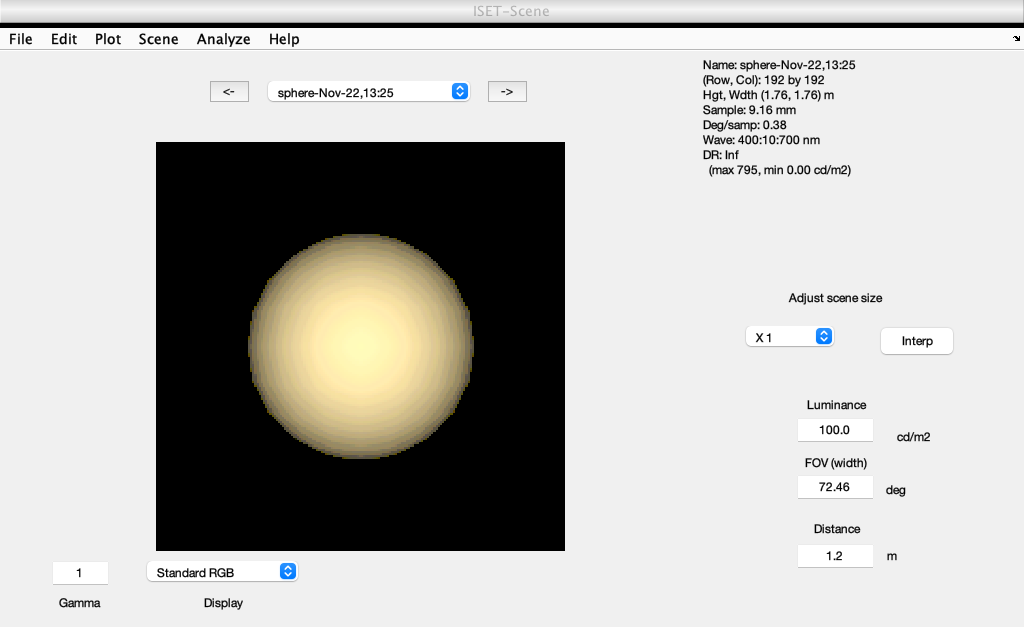

sceneWindow(scene);

dockerWrapper.getPrefs;



dockerWrapper defaults (getprefs('docker'))
________________

	verbosity		1
	whichGPU		0
	remoteRoot		'/home/wandell'
	remoteUser		'wandell'
	gpuRendering		1
	remoteImageTag		'latest'
	localRoot		''
	localRender		0
	localImageTag		'latest'
	remoteMachine		'muxreconrt.stanford.edu'
	remoteImage		'digitalprodev/pbrt-v4-gpu-ampere-mux:latest'
	renderContext		'remote-mux'
	renderString		''
	localImage		''
	defaultContext		'default'
	localVolumePath		'/iset/iset3d-v4/local/'

Configured for rendering on muxreconrt.stanford.edu using a GPU.



[scene, result] = piRender(thisR);

Put: rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t /Users/wandell/Documents/MATLAB/iset3d-v4/local/sphere/ wandell@muxreconrt.stanford.edu:/home/wandell/iset/iset3d-v4/local/sphere/ ...
Done (0.37 sec)
Command: docker --context remote-mux exec -it  pbrt-gpu-wandell1634 sh -c "cd /iset/iset3d-v4/local/sphere && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/sphere.exr sphere.pbrt"
Rendered remotely in: 2.12 sec
Pull: rsync -r  wandell@muxreconrt.stanford.edu:/home/wandell/iset/iset3d-v4/local/sphere/renderings/ /Users/wandell/Documents/MATLAB/iset3d-v4/local/sphere/renderings ...
done (  0.36 sec)

------------------
Container command: docker --context remote-mux exec -it  pbrt-gpu-wandell1634 sh -c "cd /iset/iset3d-v4/local/sphere && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/sphere.exr sphere.pbrt"
PBRT command: pbrt --gpu --outfile renderings/sphere.exr sphere.pbrt

------------------

Output file:  renderings/sphere.exr
*** Rendering ti

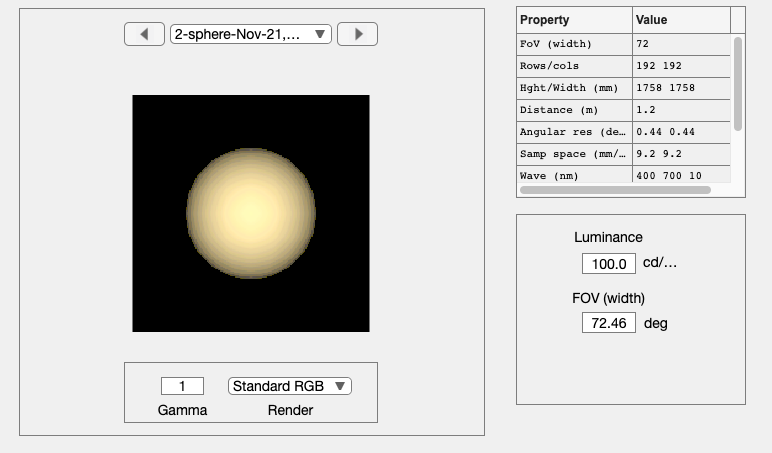

sceneWindow(scene);

## By default, piRender computes the scene or oi depth map

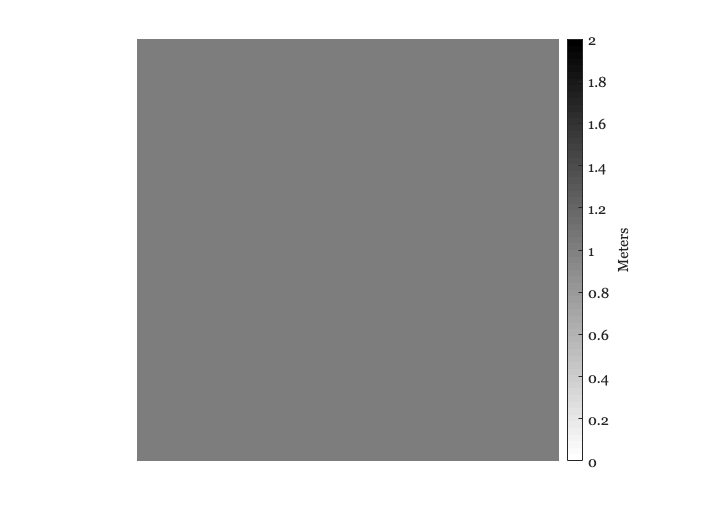

scenePlot(scene,'depth map');

## Change the light to a bluish light

You can edit the lights this way, adding a light which is more blue and distant 

% Remove the light we added
thisR.set('light',thisLight.name, 'delete');

% Create a new version with a different color temperature
thisLight = piLightCreate('distant','type','distant',  'spd', 9000,  'cameracoordinate', true);
thisR.set('light',thisLight, 'add');

This is an efficient way to Write, Render and Show without the separate calls.

Put: rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t /Users/wandell/Documents/MATLAB/iset3d-v4/local/sphere/ wandell@muxreconrt.stanford.edu:/home/wandell/iset/iset3d-v4/local/sphere/ ...
Done (0.39 sec)
Command: docker --context remote-mux exec -it  pbrt-gpu-wandell1634 sh -c "cd /iset/iset3d-v4/local/sphere && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/sphere.exr sphere.pbrt"
Rendered remotely in: 2.21 sec
Pull: rsync -r  wandell@muxreconrt.stanford.edu:/home/wandell/iset/iset3d-v4/local/sphere/renderings/ /Users/wandell/Documents/MATLAB/iset3d-v4/local/sphere/renderings ...
done (  0.35 sec)

------------------
Container command: docker --context remote-mux exec -it  pbrt-gpu-wandell1634 sh -c "cd /iset/iset3d-v4/local/sphere && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/sphere.exr sphere.pbrt"
PBRT command: pbrt --gpu --outfile renderings/sphere.exr sphere.pbrt

------------------

Output file:  renderings/sphere.exr
*** Rendering ti

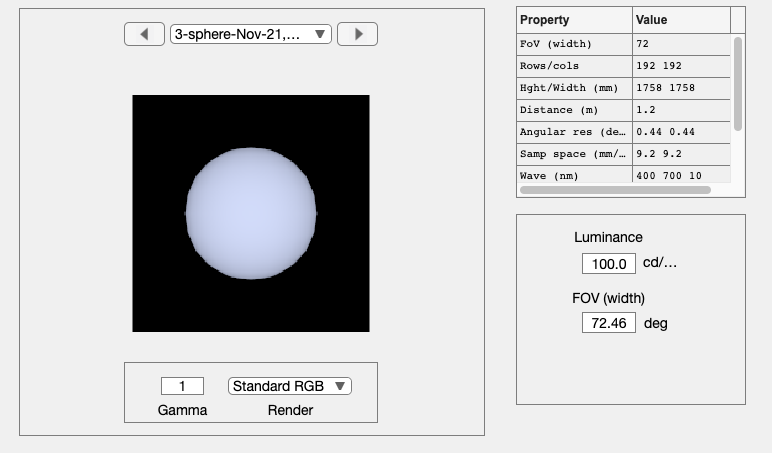

piWRS(thisR);

## Read an  FBX file and write it as PBRT

% FBX is converted into PBRT
fname = fullfile(piRootPath,'data','scenes','teapot-set','TeaTime-converted.pbrt');
 
thisR  = piRead(fname);

Setting integrator to "path" with 5 bounces.Read 6 materials and 1 textures..


Convert scene unit from centimeter to meter

thisR.set('film resolution',[600 600]/2);
thisR.set('rays per pixel',32);

Set the render type.

One type is radiance, and here are the others

**rTypes = {'radiance','depth','both','all','coordinates','material','instance', 'illuminant','illuminantonly'};**

thisR.set('film render type',{'radiance','depth'});

%% move object
thisR.set('asset','Cylinder.001_B','world translation',[0.2 0 0]);

thisR.show('objects');

                                           material            positions (m)           sizes (m)   
                                       ________________    _____________________    _______________

    000006ID_001_Cylinder.001_O        {'Stone'       }    {'6.39 5.47 16.50'  }    {'NaN NaN NaN'}
    000008ID_002_Cylinder.001_O        {'Rubber'      }    {'6.39 5.47 16.50'  }    {'NaN NaN NaN'}
    000010ID_003_Cylinder.001_O        {'Porcelain'   }    {'6.39 5.47 16.50'  }    {'NaN NaN NaN'}
    000012ID_001_004_Cylinder.001_O    {'Wood'        }    {'6.59 5.47 16.50'  }    {'NaN NaN NaN'}
    000015ID_001_Cylinder.004_O        {'Stone'       }    {'-8.18 5.47 11.67' }    {'NaN NaN NaN'}
    000017ID_002_Cylinder.004_O        {'Rubber'      }    {'-8.18 5.47 11.67' }    {'NaN NaN N

## Add a light

Put: rsync  --protocol=29  -e "ssh -x -T -o Compression=no" -r -t /Users/wandell/Documents/MATLAB/iset3d-v4/local/TeaTime-converted/ wandell@muxreconrt.stanford.edu:/home/wandell/iset/iset3d-v4/local/TeaTime-converted/ ...
Done (0.48 sec)
Command: docker --context remote-mux exec -it  pbrt-gpu-wandell1634 sh -c "cd /iset/iset3d-v4/local/TeaTime-converted && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/TeaTime-converted.exr TeaTime-converted.pbrt"
Rendered remotely in: 2.89 sec
Pull: rsync -r  wandell@muxreconrt.stanford.edu:/home/wandell/iset/iset3d-v4/local/TeaTime-converted/renderings/ /Users/wandell/Documents/MATLAB/iset3d-v4/local/TeaTime-converted/renderings ...
done (  0.42 sec)

------------------
Container command: docker --context remote-mux exec -it  pbrt-gpu-wandell1634 sh -c "cd /iset/iset3d-v4/local/TeaTime-converted && rm -rf renderings/{*,.*}  && pbrt --gpu --outfile renderings/TeaTime-converted.exr TeaTime-converted.pbrt"
PBRT command: pbrt --gpu --outfi

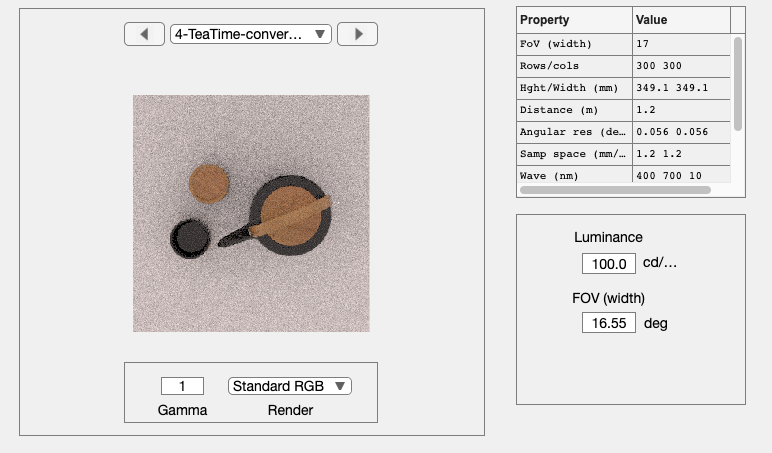

piLightDelete(thisR, 'all'); 
lightName = 'new light';
newLight = piLightCreate(lightName,...
                        'type','infinite',...
                        'spd',[0.4 0.3 0.3],...
                        'specscale',1);
thisR.set('light', newLight, 'add');

% Render and return the scene
scene = piWRS(thisR);

Show the geometry

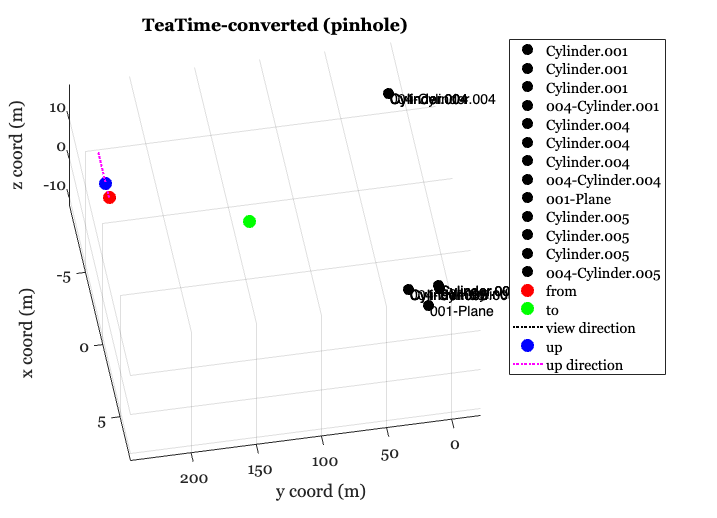

piAssetGeometry(thisR);view(-80,-65);